
[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\afro_mnist_ethiopic.mat


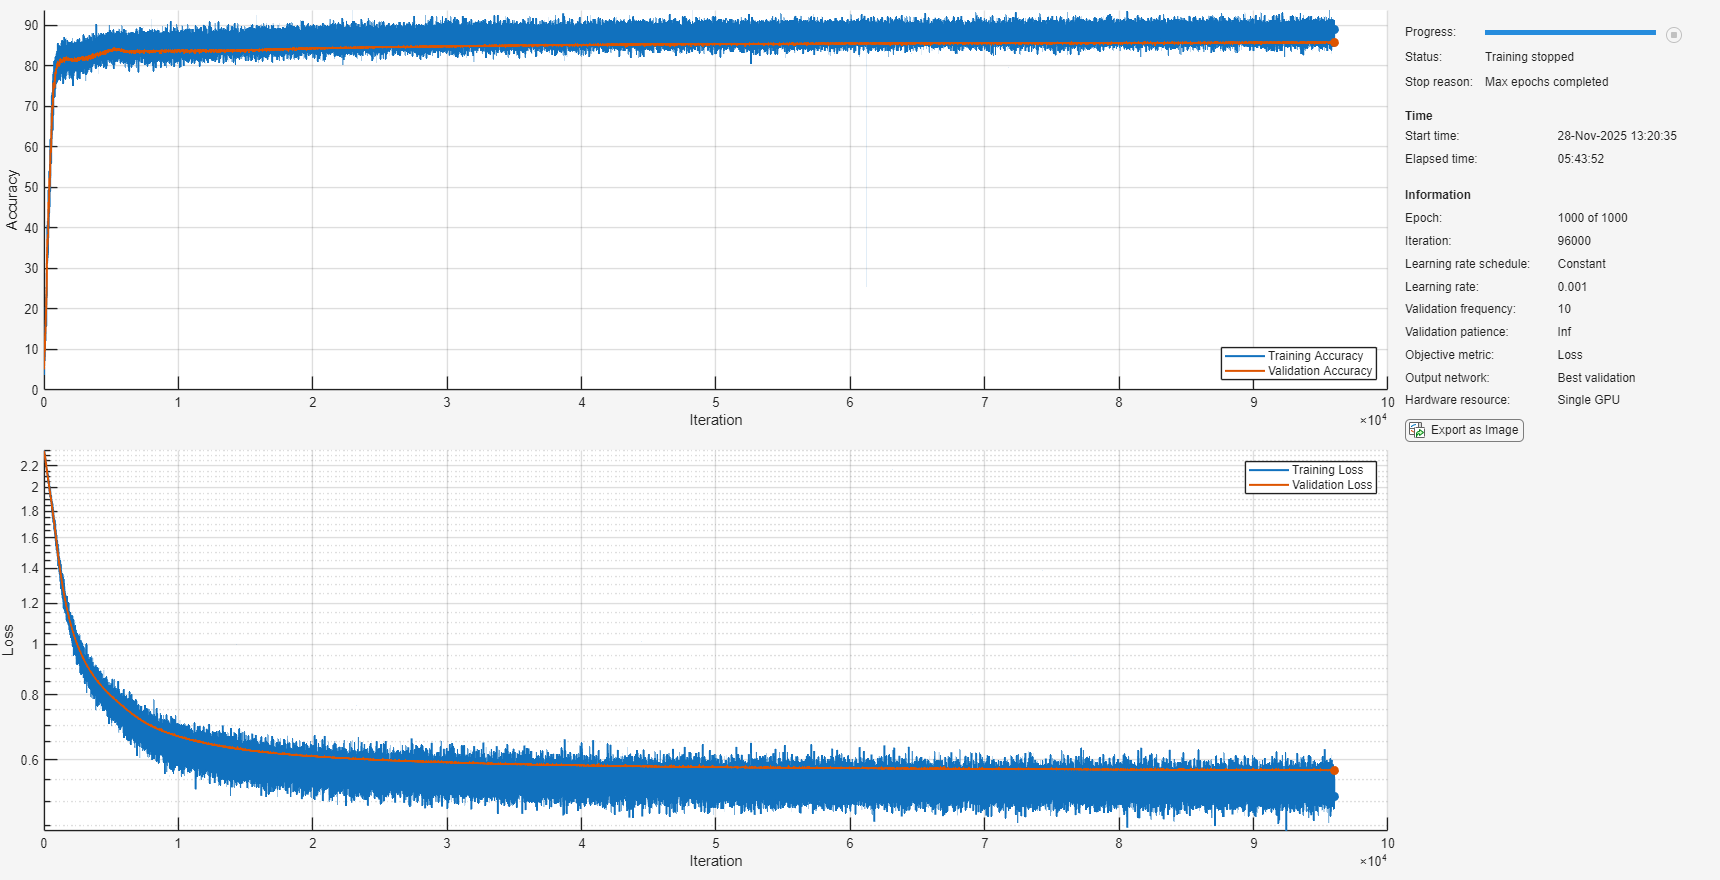

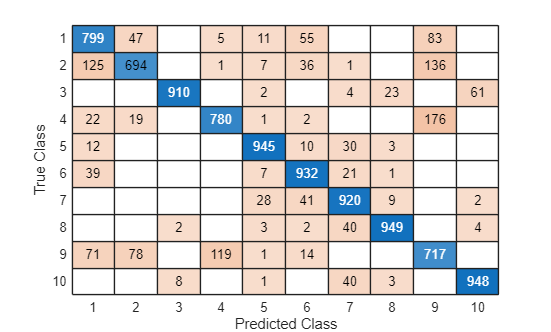

[afro_mnist_ethiopic.mat] Test Accuracy: 85.94%



[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\afro_mnist_nko.mat


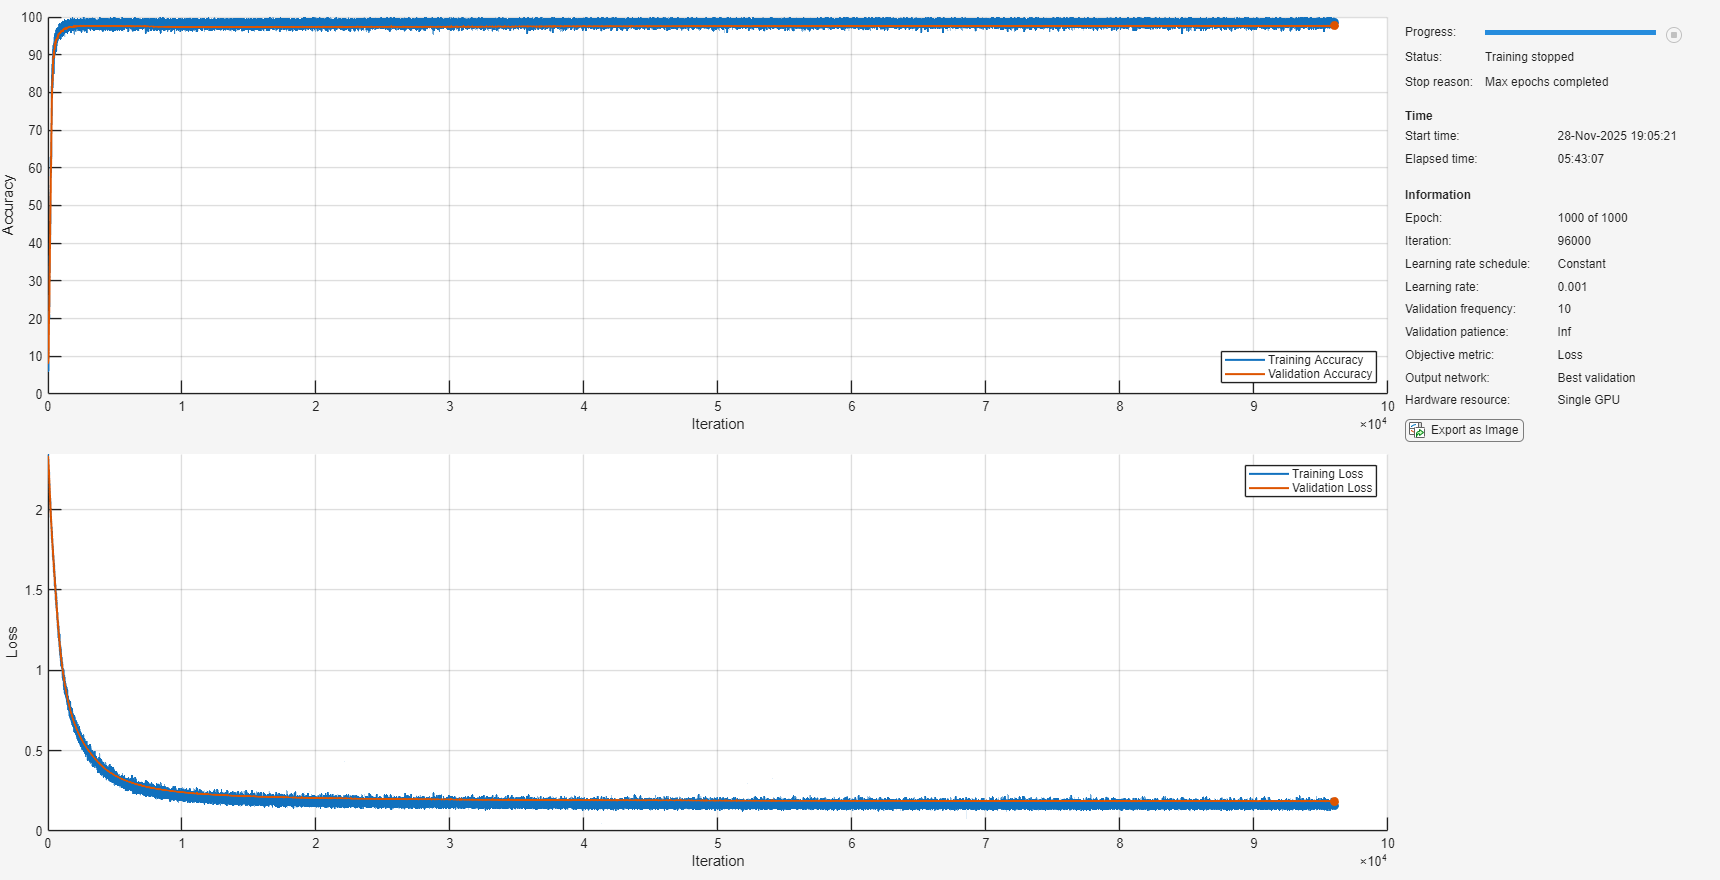

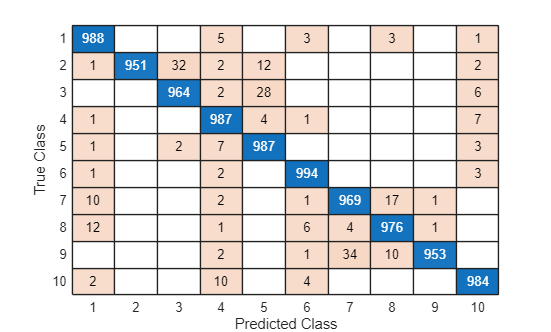

[afro_mnist_nko.mat] Test Accuracy: 97.53%



[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\afro_mnist_osmanya.mat


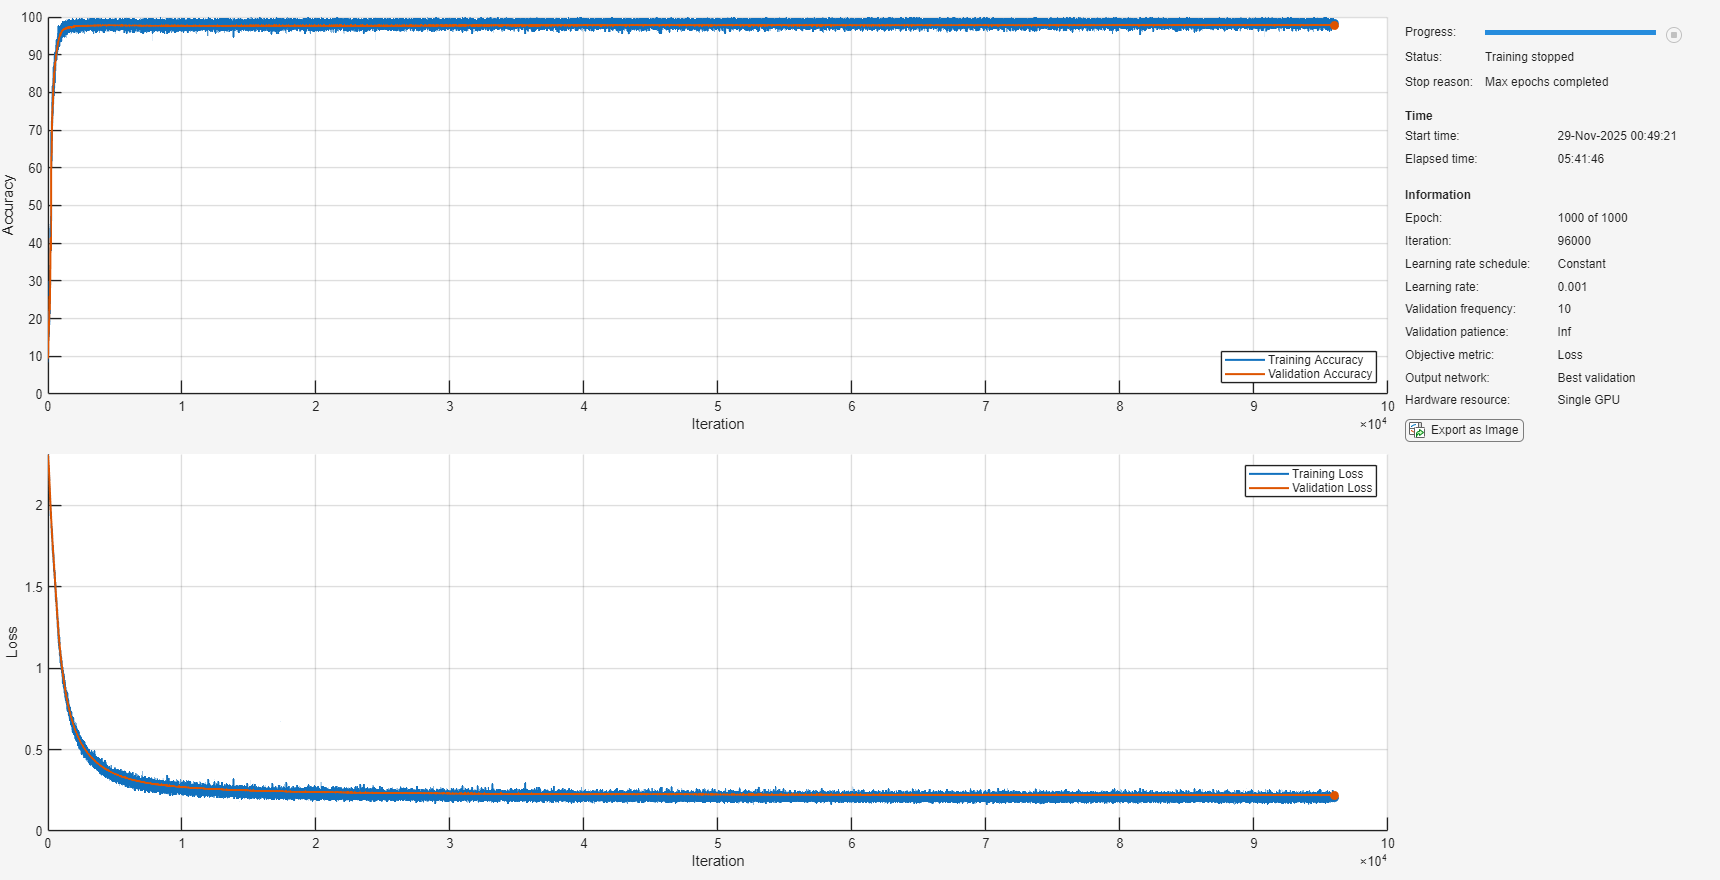

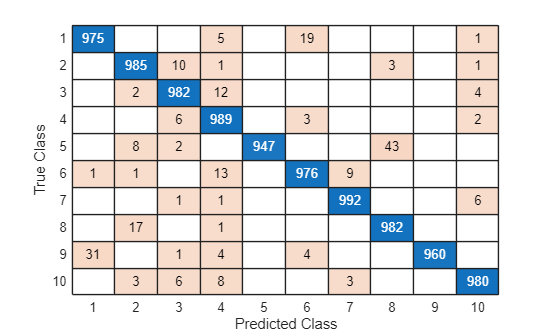

[afro_mnist_osmanya.mat] Test Accuracy: 97.68%



[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\afro_mnist_vai.mat


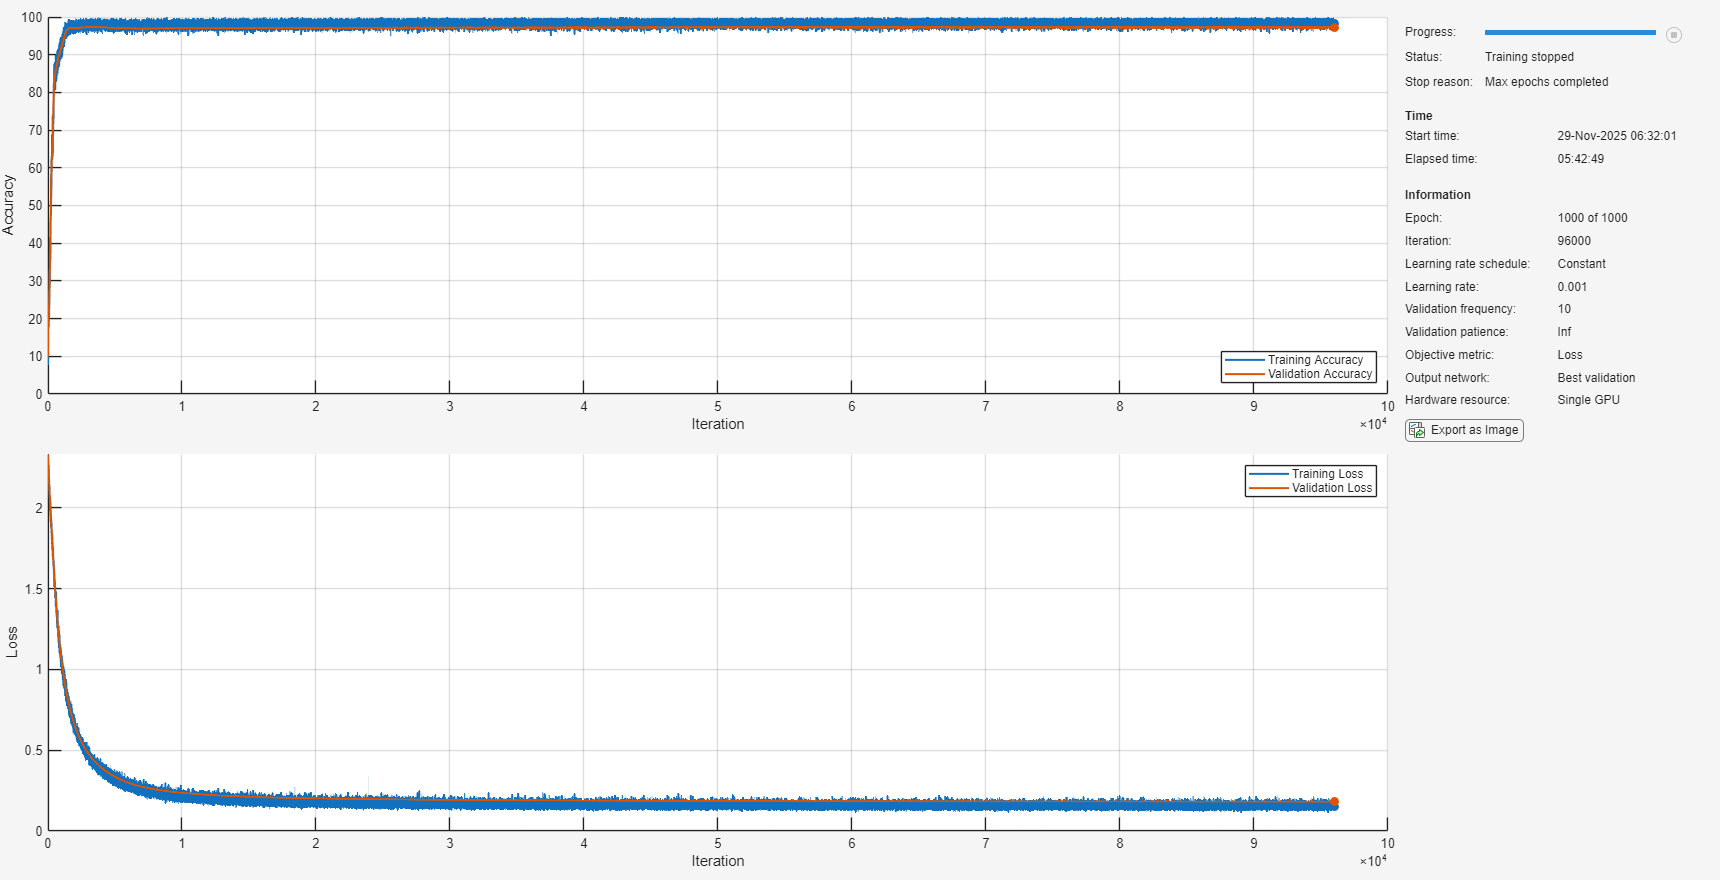

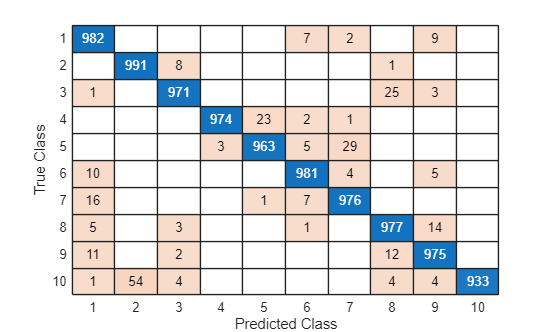

[afro_mnist_vai.mat] Test Accuracy: 97.23%



[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\kmnist.mat


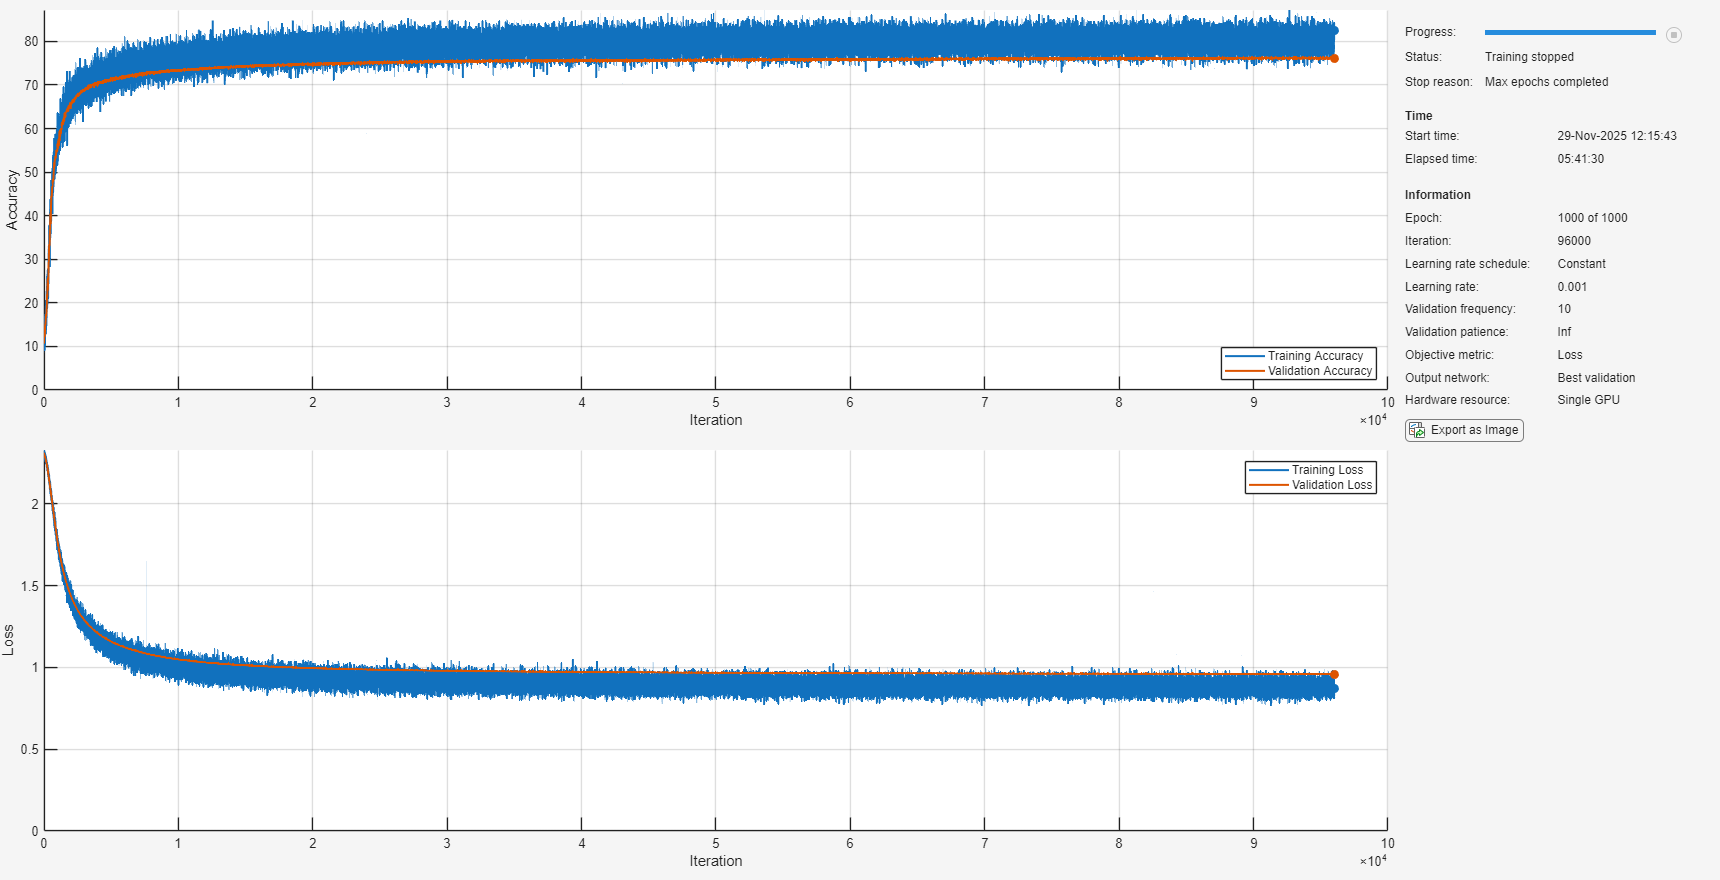

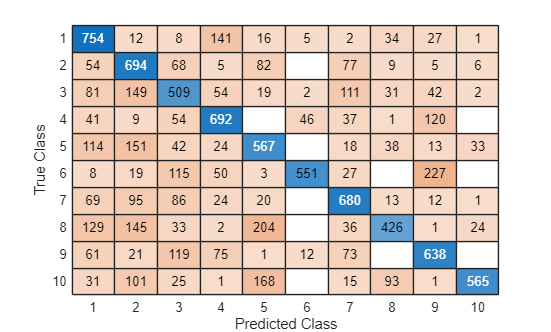

[kmnist.mat] Test Accuracy: 60.76%



[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\mnist_fashion.mat


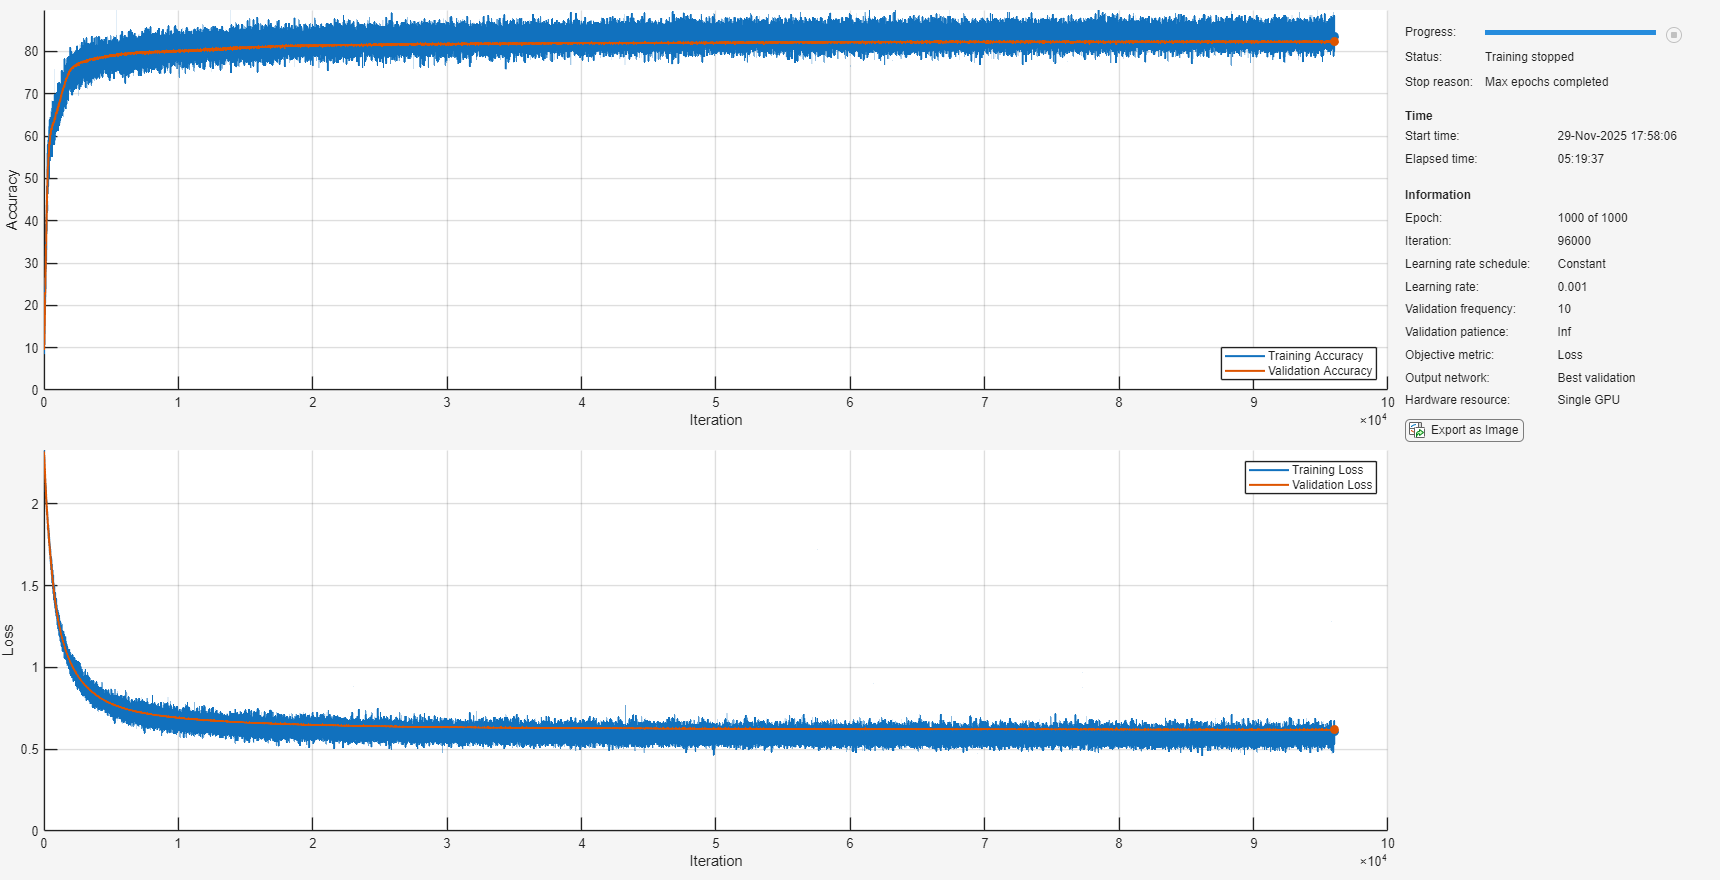

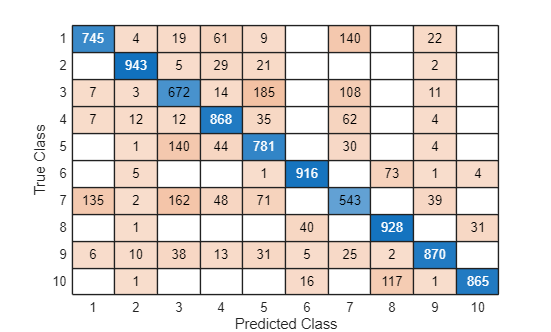

[mnist_fashion.mat] Test Accuracy: 81.31%



[Dataset] C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Datasets\mnist.mat


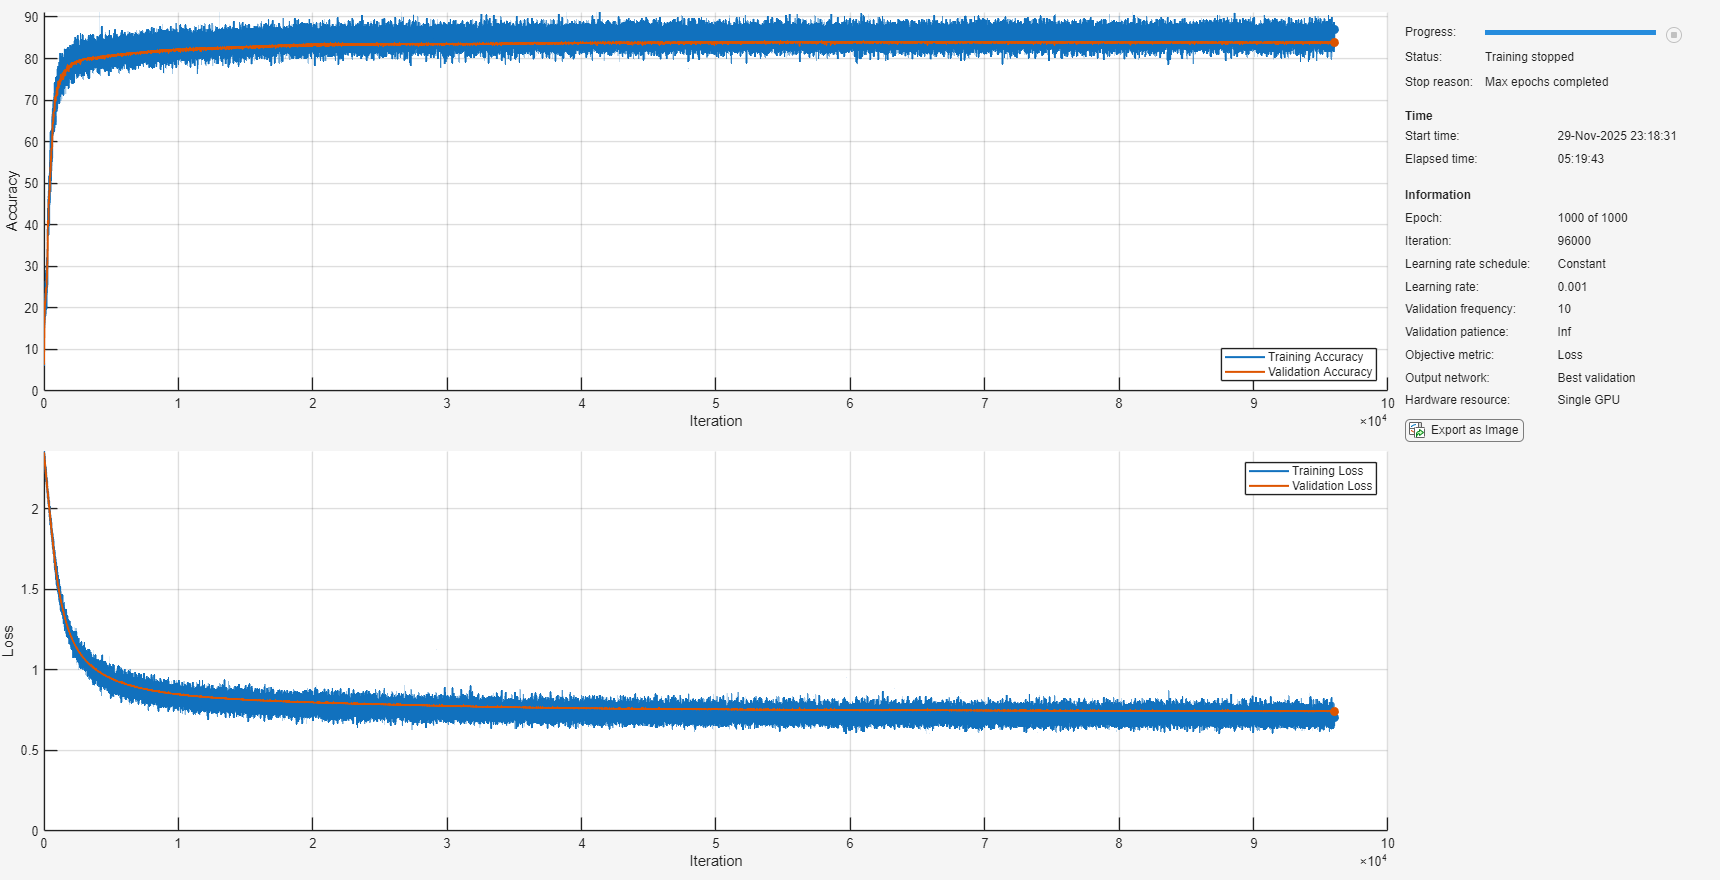

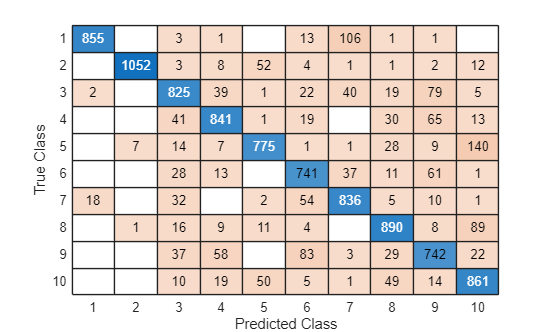

[mnist.mat] Test Accuracy: 84.18%


%% train_mnist_variants_release.m
% Public release script for training a simple (frozen) classifier
% on MNIST and MNIST-like datasets (Fashion-MNIST, KMNIST, Afro-MNIST
% variants for Ethiopic, N'Ko, Osmanya, and Vai).
%
% Requirements
% ------------
% * MATLAB R2023b or later recommended (tested with R2024b)
% * Deep Learning Toolbox
% * ~12 GB RAM (the network contains large fixed fully-connected layers
%   with 16k units; see note below). A GPU is optional but helpful.
%
% Dataset files expected (place in ./data):
% ----------------------------------------
%  - 'mnist.mat'
%  - 'mnist_fashion.mat'
%  - 'kmnist.mat'
%  - 'afro_mnist_ethiopic.mat'
%  - 'afro_mnist_nko.mat'
%  - 'afro_mnist_osmanya.mat'
%  - 'afro_mnist_vai.mat'
%
% Each *.mat must contain two structs named 'training' and 'test' with
% the following fields:
%   training.images : [28 x 28 x 1 x Ntrain] single (or double) in [0,1]
%   training.labels : [Ntrain x 1] int32 (or double) with class ids 0..C-1
%   test.images     : [28 x 28 x 1 x Ntest] single (or double) in [0,1]
%   test.labels     : [Ntest x 1] int32 (or double) with class ids 0..C-1
%
% ---------------------------
% HOW TO GET THE DATA (URLs)
% ---------------------------
% MNIST (handwritten digits):
%   https://cs.nyu.edu/~yann/datasets/index.html
%
% Fashion-MNIST (Zalando):
%   https://github.com/zalandoresearch/fashion-mnist
%
% KMNIST (Kuzushiji-MNIST):
%   https://codh.rois.ac.jp/kmnist/index.html.en

%
% Afro-MNIST (Ethiopic, N'Ko, Osmanya, Vai):
%   https://daniel-wu.github.io/projects/AfroMNIST/
%   https://github.com/Daniel-Wu/AfroMNIST
%   Download and convert to MAT format with make_afromnist_to_mat.
%

%% -------------------- User-configurable section --------------------
WIDTH        = 16000;
NUM_EPOCHS   = 1000;
BATCH_SIZE   = 500;
LEARN_RATE   = 0.001;
RESULTS_DIR  = './';
DATA_DIR    = './';

if ~exist('target_list','var')
    target_list = {'afro_mnist_ethiopic.mat','afro_mnist_nko.mat', ...
                   'afro_mnist_osmanya.mat','afro_mnist_vai.mat', ...
                   'kmnist.mat','mnist_fashion.mat','mnist.mat'};
end

%% -------------------------- Main routine --------------------------
clearvars -except WIDTH NUM_EPOCHS BATCH_SIZE LEARN_RATE RESULTS_DIR DATA_DIR target_list
close all; clc;
rng(42,'twister');
if ~exist(RESULTS_DIR,'dir'); mkdir(RESULTS_DIR); end

for ii = 1:numel(target_list)
    ds_file = fullfile(DATA_DIR, target_list{ii});
    fprintf('\n====================\n[Dataset] %s\n', ds_file);

    if ~isfile(ds_file)
        warning('File not found: %s', ds_file);
        continue;
    end

    S = load(ds_file);
    training = S.training;
    test     = S.test;

    training.images = ensure_4d(training.images);
    test.images     = ensure_4d(test.images);

    training.images = im2single(training.images);
    test.images     = im2single(test.images);

    num_out = max(double(training.labels)) + 1;
    tTrain = categorical(double(training.labels) + 1);
    tTest  = categorical(double(test.labels) + 1);

    numTotal = numel(tTrain);
    idx = randperm(numTotal);
    nTrain = round(0.8 * numTotal);
    trainIdx = idx(1:nTrain);
    valIdx   = idx(nTrain+1:end);

    XTrain = training.images(:,:,:,trainIdx);
    YTrain = tTrain(trainIdx);
    XVal   = training.images(:,:,:,valIdx);
    YVal   = tTrain(valIdx);

    XTrain = normalize(XTrain,4) / sqrt(28*28);
    XVal   = normalize(XVal,4)   / sqrt(28*28);
    XTest  = normalize(test.images,4) / sqrt(28*28);
    XTrain(isnan(XTrain)) = 0; XVal(isnan(XVal)) = 0; XTest(isnan(XTest)) = 0;

    % Define the network (two frozen FC tanh layers + trainable softmax)
    % Initializers: uses your custom functions customWeights1_git/customWeights2_git/customWeights3_git.
    layers = [ ...
        imageInputLayer([28 28 1], Normalization='none')
        fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0,'WeightsInitializer',@customWeights1_git,'BiasL2Factor',0,'BiasInitializer','zeros')
        tanhLayer
        fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0,'WeightsInitializer',@customWeights2_git,'BiasL2Factor',0,'BiasInitializer','zeros')
        tanhLayer
        fullyConnectedLayer(num_out,'Name','output','WeightLearnRateFactor',0,'WeightsInitializer',@customWeights3_git,'BiasL2Factor',0,'BiasInitializer','zeros')
        softmaxLayer];

    dlnet = dlnetwork(layers);

    % Training options (keep plots enabled)
    options = trainingOptions('adam', ...
        'MaxEpochs',NUM_EPOCHS, ...
        'Metrics',["accuracy"], ...
        'MiniBatchSize',BATCH_SIZE, ...
        'InitialLearnRate',LEARN_RATE, ...
        'Shuffle','every-epoch', ...
        'ValidationData',{XVal,YVal}, ...
        'ValidationFrequency',10, ...
        'Plots','training-progress', ...
        'ExecutionEnvironment','auto', ...
        'Verbose',false);

    [net, info] = trainnet(XTrain, YTrain, dlnet, 'crossentropy', options);

    % Test set evaluation
    scores = predict(net, XTest);
    [~, predIdx] = max(scores, [], 2);
    yHat = categorical(predIdx);

    figure('Name',sprintf('Confusion - %s', target_list{ii}));
    confusionchart(tTest, yHat);

    acc = 100 * mean(yHat == tTest);
    fprintf('[%s] Test Accuracy: %.2f%%\n', target_list{ii}, acc);

    outname = erase(target_list{ii}, '.mat');
    save(fullfile(RESULTS_DIR, sprintf('%s_results.mat', outname)), 'net','info','acc');
end


%% ------------------------ Helper functions ------------------------
function X = ensure_4d(X)
    sz = size(X);
    if numel(sz)==3 && sz(3)~=1
        X = reshape(X,28,28,1,sz(3));
    elseif numel(sz)==2 && sz(1)==28*28
        N = sz(2); X = reshape(X,28,28,1,N);
    elseif numel(sz)==4
    else
        error('Unsupported image array shape.');
    end
end

% Conversion helpers omitted for brevity (same as earlier version)
